# Parameter Sweep Study - Friction on Motor Shaft

*The rotating shaft of a motor experiences friction, especially if not well lubricated. What effect does this friction have on the motor speed?*

*Understanding the effect of Breakaway and Viscous friction on a rotating shaft*

    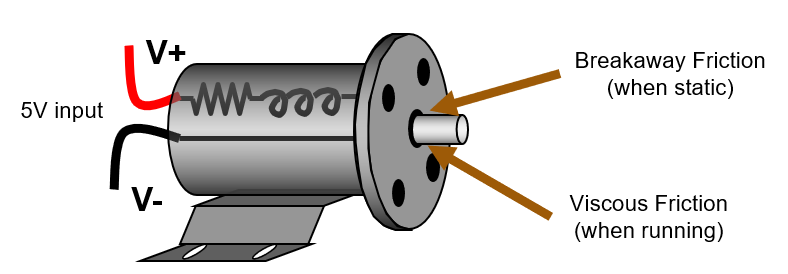

### Description

The friction torque is simulated as a function of roational velocity and is made up by 4 components - Breakaway, Stribeck, Coulomb, and Viscous - as shown in the following figure.

    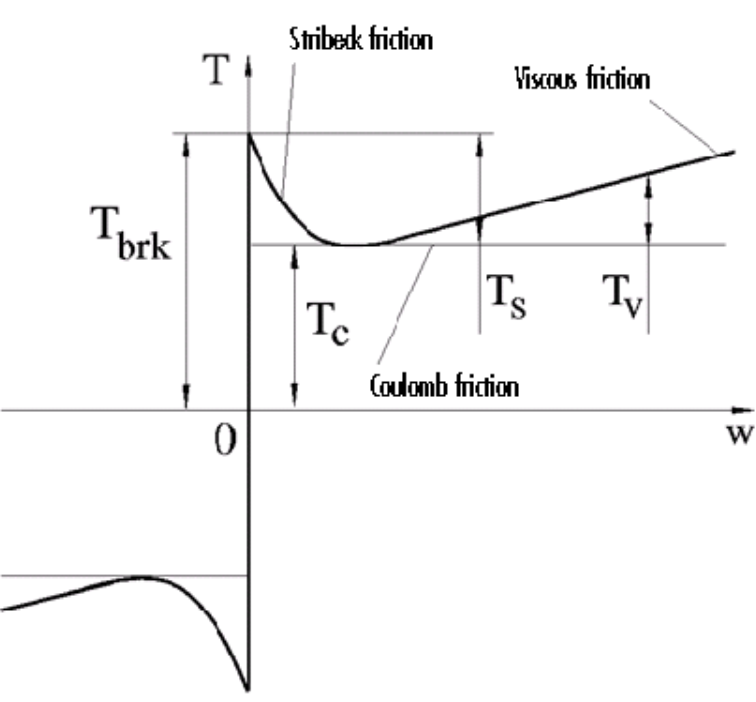

In this example, we vary the values of both the breakaway friction torque `Tbrk` and viscous friction torque `Tvis`, and review the effect on the motor speed when supplied with a constant 5V input.

## Setting up model

Ensure the model can be opened, compiled and simulated without errors.

mdl = 'ssc_dcmtr_sl';
open_system(mdl)
sim(mdl);

## Define inputs and variables that are changing

% Update the model to read from an external input
set_param('ssc_dcmtr_sl/sw', 'sw', '0')
save_system(mdl)

% Set the input to be a timetable within a Dataset
t = seconds((0:0.01:10)');
u = 5*ones(size(t));
inpt = timetable(u,'RowTimes',t);
input_ds = createInputDataset(mdl);
input_ds = input_ds.setElement(1, inpt,'externalInpt');

% Define the parameters to be varied
input_Tbreakaway = (0.001 : 0.002: 0.01)';
input_Tviscous = (0.000 : 0.005: 0.02)';

numSims = length(input_Tbreakaway)*length(input_Tviscous)

numSims = 25

Create a [Simulink.SimulationInput](https://www.mathworks.com/help/simulink/slref/simulink.simulationinput-class.html) object and set the external inputs and add variables used by the model into the Simulink.SimulationInput object.

runID = 1;
for v1 = 1:length(input_Tbreakaway)
    for v2 = 1:length(input_Tviscous)     

        in(runID) = Simulink.SimulationInput(mdl);
        in(runID) = setExternalInput(in(runID),input_ds);
        in(runID) = in(runID).setVariable('Tbrk',input_Tbreakaway(v1),'Workspace',mdl);
        in(runID) = in(runID).setVariable('Tvis',input_Tviscous(v2),'Workspace',mdl); 
        disp(['runID = ' num2str(runID) ';  Tbrk = ' num2str(input_Tbreakaway(v1)) ';  Tvis = ' num2str(input_Tviscous(v2)) ])
        
        runID = runID+1;
    end
end

runID = 1;  Tbrk = 0.001;  Tvis = 0
runID = 2;  Tbrk = 0.001;  Tvis = 0.005
runID = 3;  Tbrk = 0.001;  Tvis = 0.01
runID = 4;  Tbrk = 0.001;  Tvis = 0.015
runID = 5;  Tbrk = 0.001;  Tvis = 0.02
runID = 6;  Tbrk = 0.003;  Tvis = 0
runID = 7;  Tbrk = 0.003;  Tvis = 0.005
runID = 8;  Tbrk = 0.003;  Tvis = 0.01
runID = 9;  Tbrk = 0.003;  Tvis = 0.015
runID = 10;  Tbrk = 0.003;  Tvis = 0.02
runID = 11;  Tbrk = 0.005;  Tvis = 0
runID = 12;  Tbrk = 0.005;  Tvis = 0.005
runID = 13;  Tbrk = 0.005;  Tvis = 0.01
runID = 14;  Tbrk = 0.005;  Tvis = 0.015
runID = 15;  Tbrk = 0.005;  Tvis = 0.02
runID = 16;  Tbrk = 0.007;  Tvis = 0
runID = 17;  Tbrk = 0.007;  Tvis = 0.005
runID = 18;  Tbrk = 0.007;  Tvis = 0.01
runID = 19;  Tbrk = 0.007;  Tvis = 0.015
runID = 20;  Tbrk = 0.007;  Tvis = 0.02
runID = 21;  Tbrk = 0.009;  Tvis = 0
runID = 22;  Tbrk = 0.009;  Tvis = 0.005
runID = 23;  Tbrk = 0.009;  Tvis = 0.01
runID = 24;  Tbrk = 0.009;  Tvis = 0.015
runID = 25;  Tbrk = 0.009;  Tvis = 0.02


clear ans inpt t u v1 v2 runID

## Simulate the model

In series

set_param(mdl, 'FastRestart', 'on')
outseries = sim(in, 'ShowSimulationManager', 'on');

[06-Mar-2023 18:26:23] Running simulations...
[06-Mar-2023 18:26:27] Completed 1 of 25 simulation runs
[06-Mar-2023 18:26:28] Completed 2 of 25 simulation runs
[06-Mar-2023 18:26:28] Completed 3 of 25 simulation runs
[06-Mar-2023 18:26:29] Completed 4 of 25 simulation runs
[06-Mar-2023 18:26:29] Completed 5 of 25 simulation runs
[06-Mar-2023 18:26:30] Completed 6 of 25 simulation runs
[06-Mar-2023 18:26:30] Completed 7 of 25 simulation runs
[06-Mar-2023 18:26:30] Completed 8 of 25 simulation runs
[06-Mar-2023 18:26:31] Completed 9 of 25 simulation runs
[06-Mar-2023 18:26:31] Completed 10 of 25 simulation runs
[06-Mar-2023 18:26:32] Completed 11 of 25 simulation runs
[06-Mar-2023 18:26:32] Completed 12 of 25 simulation runs
[06-Mar-2023 18:26:33] Completed 13 of 25 simulation runs
[06-Mar-2023 18:26:34] Completed 14 of 25 simulation runs
[06-Mar-2023 18:26:35] Completed 15 of 25 simulation runs
[06-Mar-2023 18:26:35] Completed 16 of 25 simulation runs
[06-Mar-2023 18:26:36] Completed 17

In parallel

outparallel = parsim(in,'ShowSimulationManager', 'off');

[06-Mar-2023 18:26:40] Checking for availability of parallel pool...
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 4).
[06-Mar-2023 18:27:39] Starting Simulink on parallel workers...
[06-Mar-2023 18:27:55] Loading project on parallel workers...
[06-Mar-2023 18:27:55] Configuring simulation cache folder on parallel workers...
[06-Mar-2023 18:28:01] Loading model on parallel workers...
[06-Mar-2023 18:28:13] Running simulations...
[06-Mar-2023 18:28:32] Completed 1 of 25 simulation runs
[06-Mar-2023 18:28:33] Completed 2 of 25 simulation runs
[06-Mar-2023 18:28:33] Completed 3 of 25 simulation runs
[06-Mar-2023 18:28:33] Completed 4 of 25 simulation runs
[06-Mar-2023 18:28:35] Completed 5 of 25 simulation runs
[06-Mar-2023 18:28:35] Completed 6 of 25 simulation runs
[06-Mar-2023 18:28:35] Completed 7 of 25 simulation runs
[06-Mar-2023 18:28:35] Completed 8 of 25 simulation runs
[06-Mar-2023 18:28:37] Completed 9 of 2

## Working with the results in Simulink.SimulationOutput class

Plot one of the results

plot(outseries)

Analyze results with the help of plots

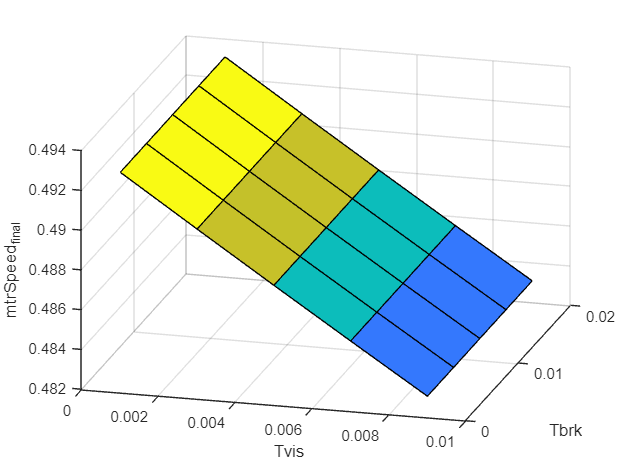

figure % Surface plot of Tbrk, Tvis, and final Motor speed

    % Create a meshgrid of input values
        [X,Y] = meshgrid(input_Tbreakaway, input_Tviscous);
        Z = X + Y;
    % Update Z with values from simulations
        runID = 1;
        for i = 1:5
            for j = 1:5
                Z(i,j) = max(outseries(1, runID).logsout{2}.Values);
                runID = runID+1;
            end
        end
    % Plot the surface plot
        surf(X,Y,Z)
        xlabel('Tvis'); ylabel('Tbrk'); zlabel('mtrSpeed_{final}');
        view([15.26287 26.62505])

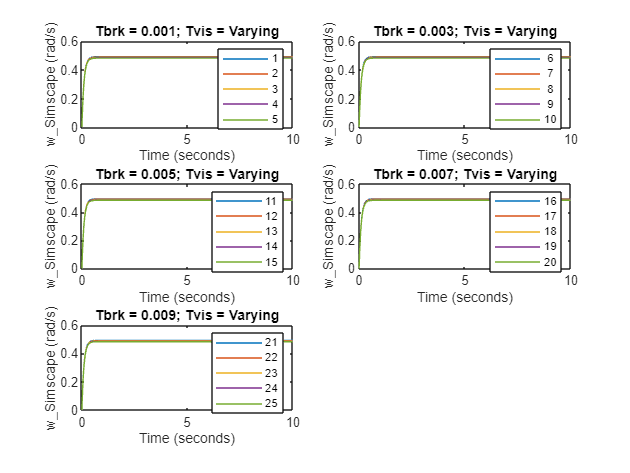

figure; % Effect of constant Tbrk on Varying Tvis
for i = 0:4
    subplot(3,2,i+1)

        nStart = (5*i)+1; % Each plot series starts at 1, 6, 11, 16, 21
        nEnd = nStart + 4;
        runs = nStart:nEnd; % All the 5 runs that have the same Tbrk

        for j = nStart:nEnd
            plot(outseries(1,j).logsout{2}.Values)
            hold on
        end
       hold off

       legend(cellstr(num2str(runs')))
       title (['Tbrk = ' num2str(input_Tbreakaway(i+1)) '; Tvis = Varying'])
end

clear i j runs X Y Z runID

### **Inferences from the data**

The results show 

- The settling motor speed `motorspeed` is affected by both `Tbrk` and `Tvis`

- `Tvis` is independent of `Tbrk`  

## Additional: Comparing Series vs Parllel Simulation speeds

Look at timing information

figure;
totaltime = zeros(1,numSims);
for i = 1:numSims
    totaltime(i) = outseries(i).SimulationMetadata.TimingInfo.TotalElapsedWallTime;
end
disp(['Average Simulation Time = ', num2str(mean(totaltime))])

Average Simulation Time = 0.42734


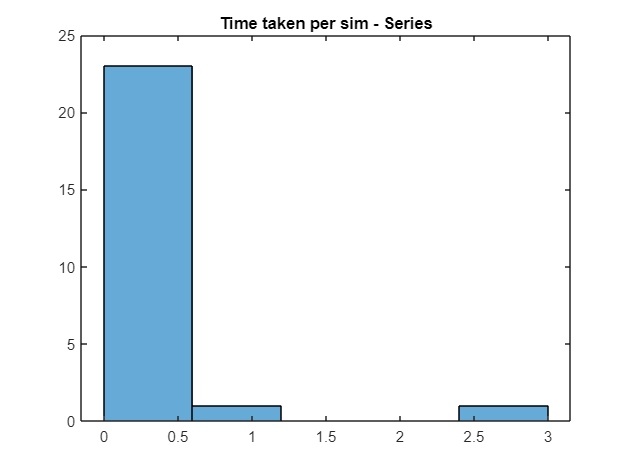

histogram(totaltime,5)
title('Time taken per sim - Series')

figure;
totaltime = zeros(1,numSims);
for i = 1:numSims
    totaltime(i) = outparallel(i).SimulationMetadata.TimingInfo.TotalElapsedWallTime;
end
disp(['Average Simulation Time = ', num2str(mean(totaltime))])

Average Simulation Time = 4.2529


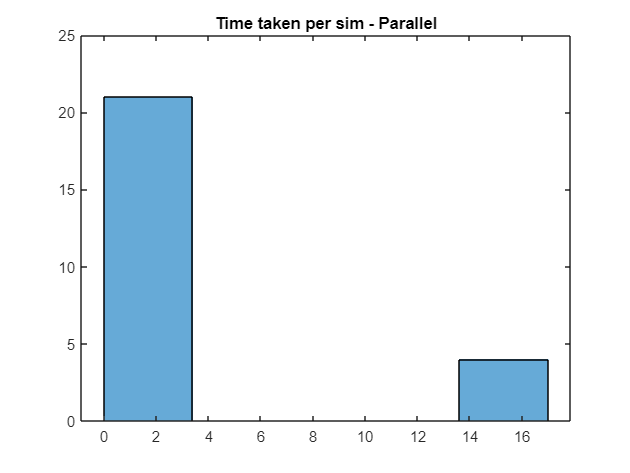

histogram(totaltime,5)
title('Time taken per sim - Parallel')

clear i totaltime

## Clean up

set_param(mdl, 'FastRestart', 'off')
set_param('ssc_dcmtr_sl/sw', 'sw', '1')
save_system(mdl)
Simulink.sdi.close
close_system(mdl)